# Configure Monocular Fisheye Camera

This example shows how to convert a fisheye camera model to a pinhole model and construct a corresponding monocular camera sensor simulation. In this example, you learn how to calibrate a fisheye camera and configure a [`monoCamera`](docid:driving_ref#bvgu10o-1) object.

## Overview

To simulate a monocular camera sensor mounted in a vehicle, follow these steps:

- Estimate the intrinsic camera parameters by calibrating the camera using a checkerboard. The intrinsic parameters describe the properties of the fisheye camera itself.

- Estimate the extrinsic camera parameters by calibrating the camera again, using the same checkerboard from the previous step. The extrinsic parameters describe the mounting position of the fisheye camera in the vehicle coordinate system.

- Remove image distortion by converting the fisheye camera intrinsics to pinhole camera intrinsics. These intrinsics describe a synthetic pinhole camera that can hypothetically generate undistorted images.

- Use the intrinsic pinhole camera parameters and the extrinsic parameters to configure the monocular camera sensor for simulation. You can then use this sensor to detect objects and lane boundaries.

## Estimate Fisheye Camera Intrinsics

To estimate the intrinsic parameters, use a checkerboard for camera calibration. Alternatively, to better visualize the results, use the [Camera Calibrator](docid:vision_ref#burd_hd-1) app. For fisheye camera, it is useful to place the checkerboard close to the camera, in order to capture large noticeable distortion in the image.

 % Gather a set of calibration images.
images = imageDatastore(fullfile(toolboxdir('vision'), 'visiondata', ...
      'calibration', 'gopro'));
imageFileNames = images.Files;
 
% Detect calibration pattern.
[imagePoints, boardSize] = detectCheckerboardPoints(imageFileNames);

% Generate world coordinates of the corners of the squares.
squareSize = 0.029; % Square size in meters
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Calibrate the camera.
I = readimage(images, 1); 
imageSize = [size(I, 1), size(I, 2)];
params = estimateFisheyeParameters(imagePoints, worldPoints, imageSize);

## Estimate Fisheye Camera Extrinsics

To estimate the extrinsic parameters, use the same checkerboard to estimate the mounting position of the camera in the vehicle coordinate system.  The following step estimates the parameters from one image. You can also take multiple checkerboard images to obtain multiple estimations, and average the results.

% Load a different image of the same checkerboard, where the checkerboard 
% is placed on the flat ground. Its X-axis is pointing to the right of the 
% vehicle, and its Y-axis is pointing to the camera. The image includes 
% noticeable distortion, such as along the wall next to the checkerboard.

imageFileName = fullfile(toolboxdir('driving'), 'drivingdata', 'checkerboard.png');
I = imread(imageFileName);
imshow(I)

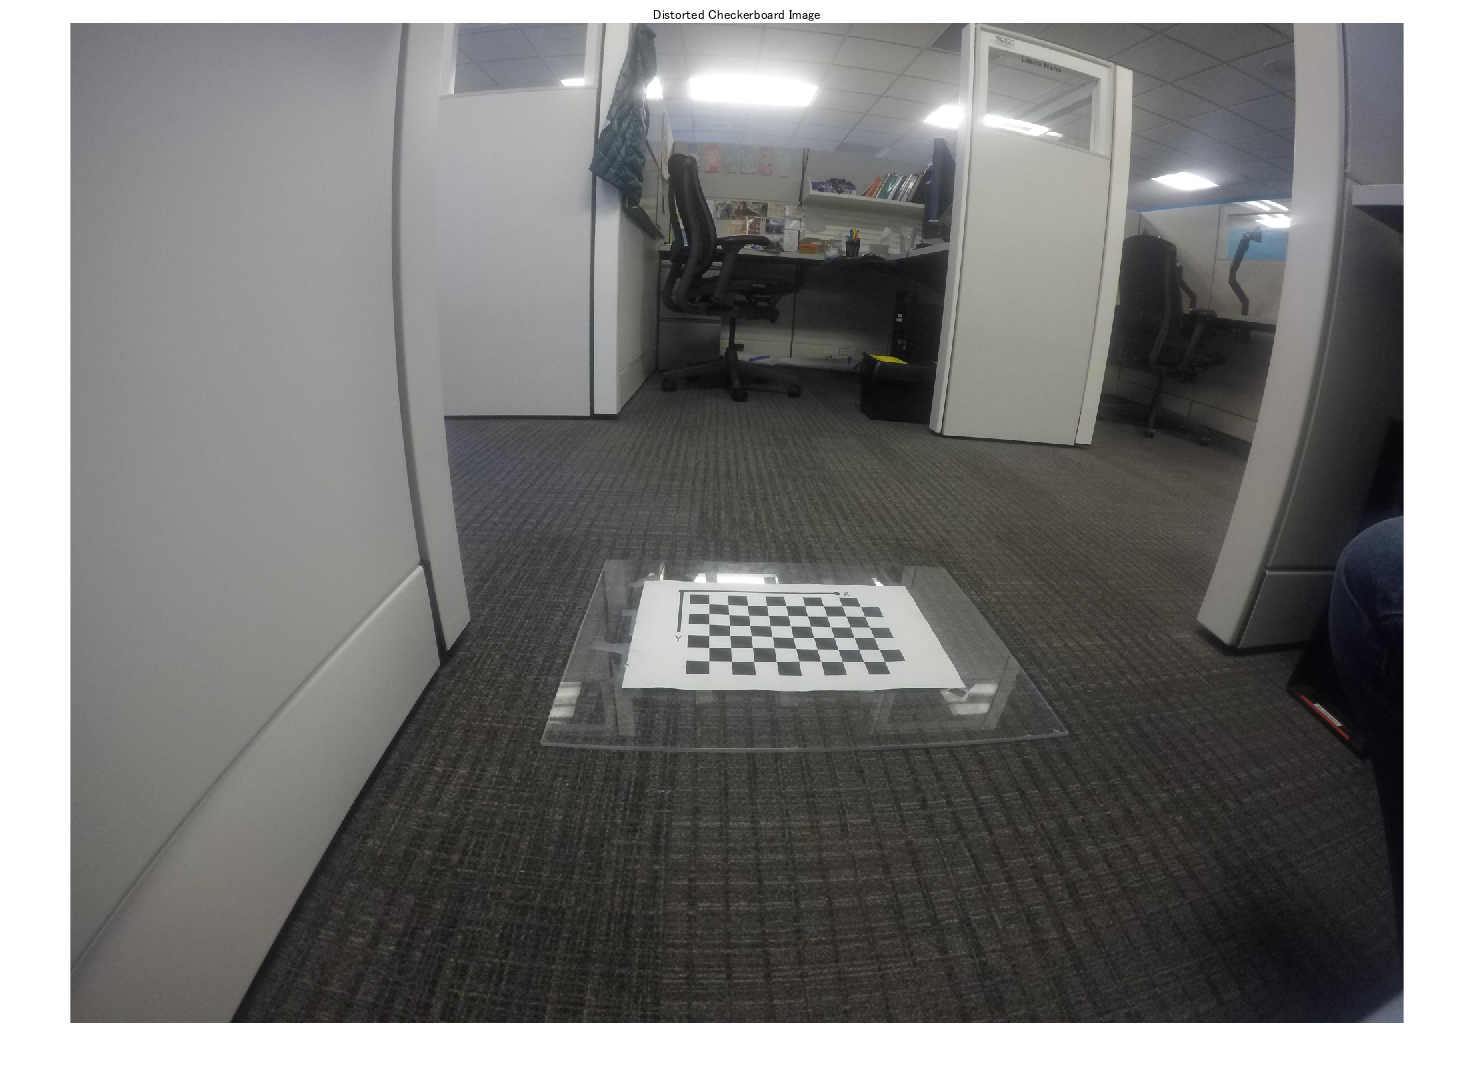

title('Distorted Checkerboard Image');


[imagePoints, boardSize] = detectCheckerboardPoints(I);
 
% Generate coordinates of the corners of the squares.
squareSize = 0.029; % Square size in meters
worldPoints = generateCheckerboardPoints(boardSize, squareSize);
 
% Estimate the parameters for configuring the monoCamera object. 
% Height of the checkerboard is zero here, since the pattern is 
% directly on the ground.
originHeight = 0;
[pitch, yaw, roll, height] = estimateMonoCameraParameters(params.Intrinsics, ...
                               imagePoints, worldPoints, originHeight);
                           

## Construct a Synthetic Pinhole Camera for the Undistorted Image

% Undistort the image and extract the synthetic pinhole camera intrinsics.
[J1, camIntrinsics] = undistortFisheyeImage(I, params.Intrinsics, 'Output', 'full');
imshow(J1)

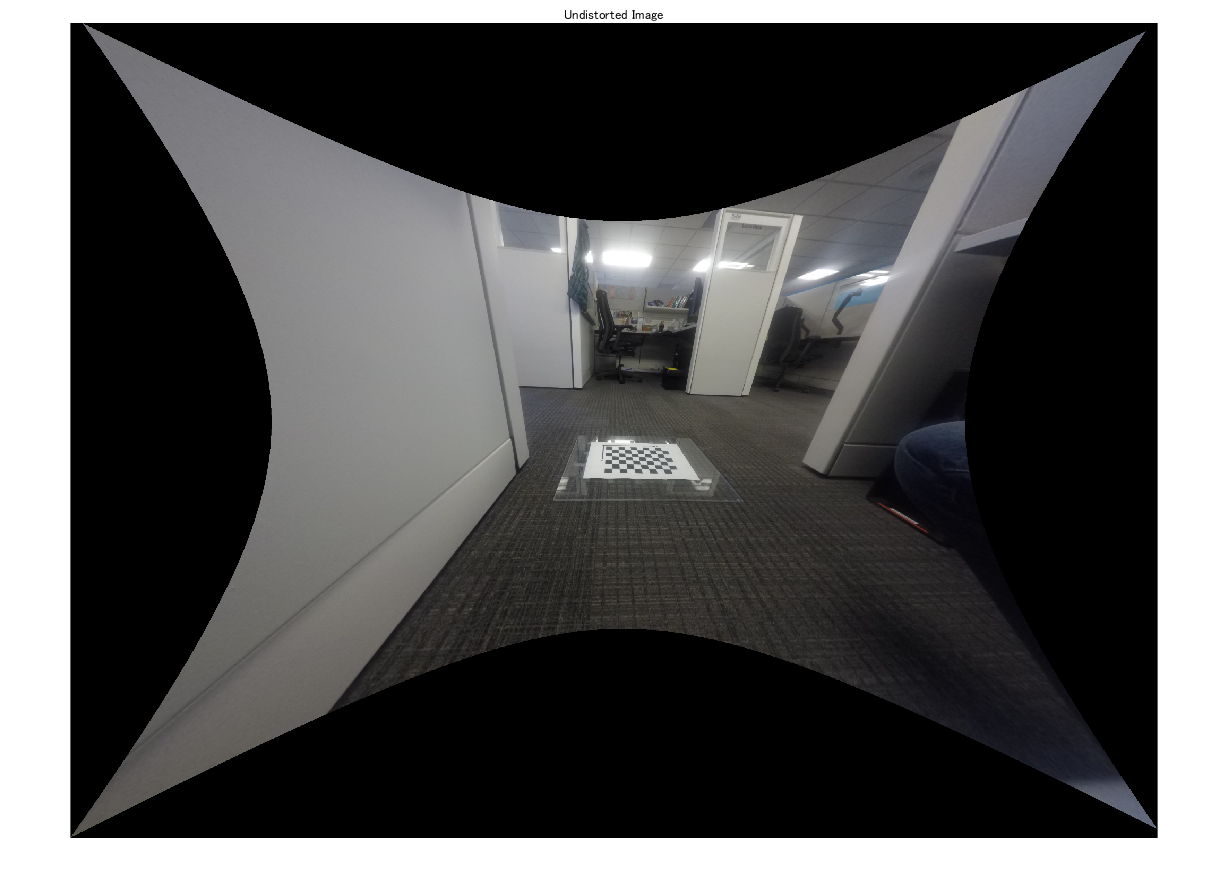

title('Undistorted Image');


% Set up monoCamera with the synthetic pinhole camera intrinsics. 
% Note that the synthetic camera has removed the distortion.
sensor = monoCamera(camIntrinsics, height, 'pitch', pitch, 'yaw', yaw, 'roll', roll);

## Plot Bird's Eye View

Now you can validate the [`monoCamera`](docid:driving_ref#bvgu10o-1) by plotting a bird's-eye view.

% Define bird's-eye-view transformation parameters
distAheadOfSensor = 6; % in meters
spaceToOneSide = 2.5;  % look 2.5 meters to the right and 2.5 meters to the left
bottomOffset = 0.2;  % look 0.2 meters ahead of the sensor
outView = [bottomOffset, distAheadOfSensor, -spaceToOneSide, spaceToOneSide];
outImageSize = [NaN,1000]; % output image width in pixels

birdsEyeConfig = birdsEyeView(sensor, outView, outImageSize);

% Transform input image to bird's-eye-view image and display it
B = transformImage(birdsEyeConfig, J1);

% Place a 2-meter marker ahead of the sensor in bird's-eye view
imagePoint0 = vehicleToImage(birdsEyeConfig, [2, 0]);
annotatedB = insertMarker(B, imagePoint0 - 5);
annotatedB = insertText(annotatedB, imagePoint0, '2 meters');

figure
imshow(annotatedB)

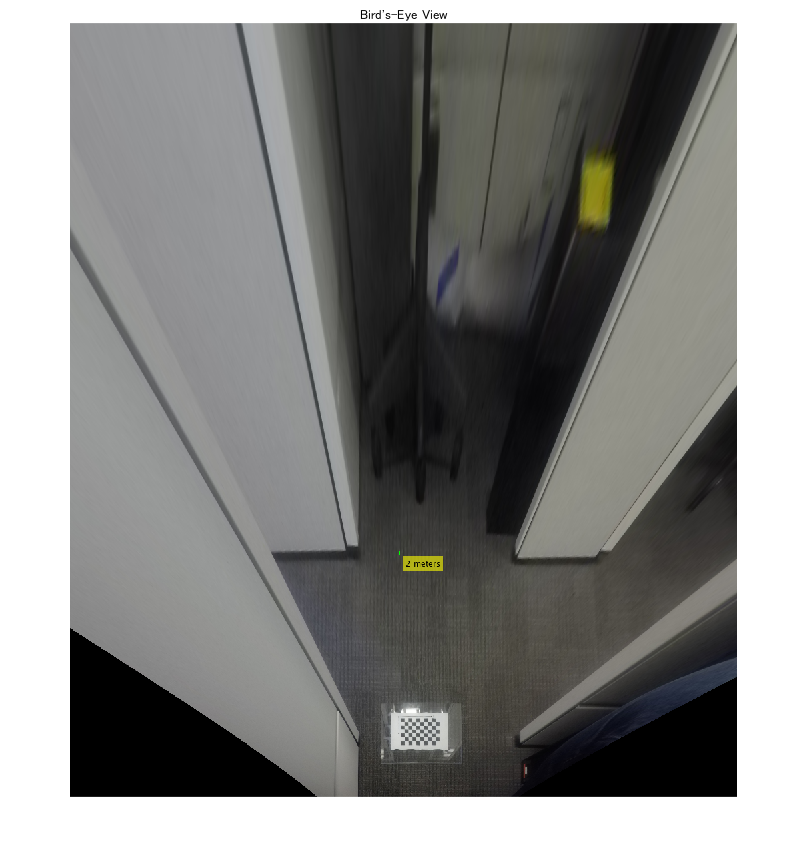

title('Bird''s-Eye View')

The plot above shows that the camera measures distances accurately. Now you can use the monocular camera for object and lane boundary detection. See the [Visual Perception Using Monocular Camera](docid:driving_examples#mw_b13b3ce9-9de9-4d94-a014-13a01f2ca568) example.

*Copyright 2018 The MathWorks, Inc.*